# **Master Document**

## Toy Example:

Using DS421 participant survey data, create two sets of figures:

1) Box-whisker plot for each criteria to show the spread amongst papers read

2) Scatter plot matrix of each criteria against every other criteria

Script organized as follows:

- Directory setting

- Data loading

- Plotting box-whisker

- Plotting scatter matrix with trendline

- Functions

Before running please make sure the directory path is set to where "/matlab_toy" located 

%Clear GUI, figures, and workspace
clc
clear
close all

%Edit 'master_dir' to point to /matlab_toy
master_dir = '/Users/solkim/Documents/PhD/yr_2/2018_Fall/GEOG257/matlab_toy'

master_dir = '/Users/solkim/Documents/PhD/yr_2/2018_Fall/GEOG257/matlab_toy'

cd(master_dir)
addpath(genpath(master_dir)) %Adds sub-directories as well

%Check to make sure you are in the correct directory
dir_check = pwd;
dir_check = dir_check(end-10:end);
if ~isequal(dir_check,'/matlab_toy')
    error('Please edit the variable master_dir to point to /matlab_toy')
else
    disp('Directory set correctly')
end

Directory set correctly


## **Load data**

Survey responses are stored in /matlab_toy/data. Load paper averages per criteria. 

%Data file
data_file = which('DS421_survey_responses.xlsx') %Finds file within master directory

data_file = '/Users/solkim/Documents/PhD/yr_2/2018_Fall/GEOG257/matlab_toy/data/DS421_survey_responses.xlsx'

%Load numeric and text data from sheet 'FinalTable'
[num,txt] = xlsread(data_file,'FinalTable');
%Clean text data
criteria = txt(1,2:end)'

criteria = 10×1 cell array
    {'Modular Workflow'                  }
    {'Data Products'                     }
    {'MRE'                               }
    {'Author Engagement'                 }
    {'Maintenance'                       }
    {'Readability'                       }
    {'Explicit Workflow'                 }
    {'User-friendly, Open Access Formats'}
    {'Re-analysis'                       }
    {'Extension'                         }


## **Plot**

Box-whisker plots

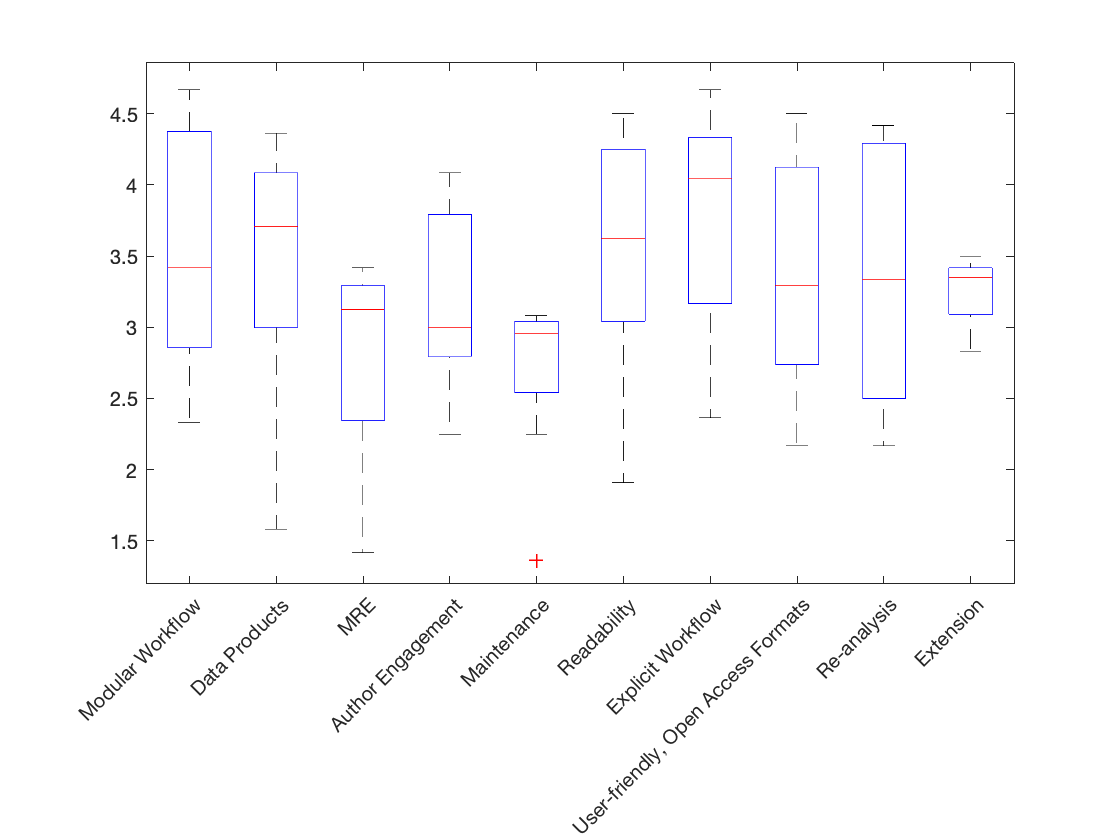

plot_axes =   Axes with properties:

             XLim: [0.5000 10.5000]
             YLim: [1.1974 4.8555]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.3046 0.7750 0.6204]
            Units: 'normalized'

  Show all properties


%Make box-whisker plot for each criteria with survey data averages per paper
fig_1 = figure;
boxplot(num,criteria)
plot_axes = gca;
plot_axes.XTickLabelRotation = 45

Scatter plots

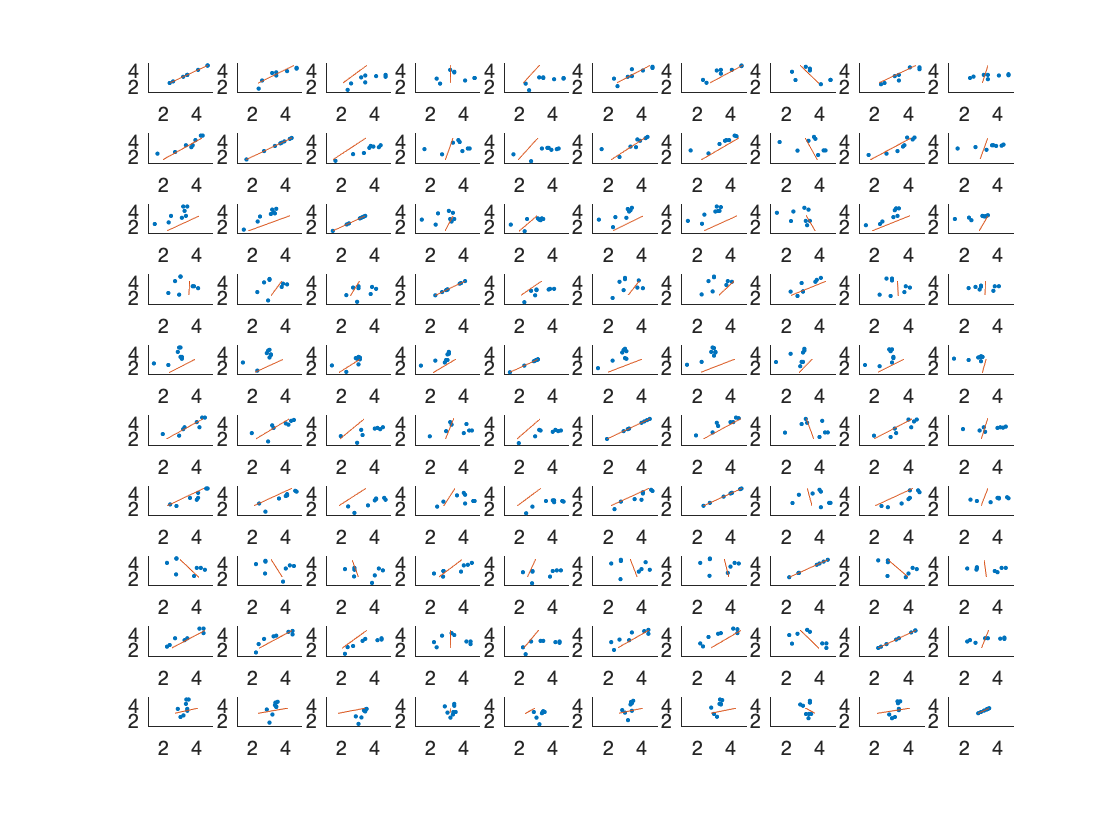


%Make matrix of scatter plots
fig_2 = figure;
subplot_ind = 0;
for i = 1:10
    for j = 1:10
        subplot_ind = subplot_ind + 1;
        subplot(10,10,subplot_ind)
        x = num(:,i);
        y = num(:,j);
        scatter(x,y,'.')
        axis([1 5 1 5])
        hold on
        y2 = linear_reg(x,y);
        plot(y2,x);
    end
end

## **Functions**

function y2 = linear_reg(x,y)

%Linear regression
%Least-squares
%
%y = mx + b
%
%Using provided x and y values, calculate m and b
%Return y2 which is x fit to y=mx + b

%Check sizes
if ~isequal(size(x),size(y))
    error('Size of x and y do not match')
end

x_sum = sum(x);
y_sum = sum(y);
xy_sum = sum(x.*y);
x_sq_sum = sum(x.^2);
n = max(size(x));

m = ((n*xy_sum)-(x_sum*y_sum))/((n*x_sq_sum)-(x_sum*x_sum));
b = ((x_sq_sum*y_sum)-(x_sum*xy_sum))/((n*x_sq_sum)-(x_sum*x_sum));

y2 = m.*x+b;
end